Vectorisation de la surface de l'équation d'état de Van der Walls avec correction

%Paramètres
Trmin = 0.5;
Trmax = 2;
Vrmin = 0.4; % la forme réduite n'est pas défini en Vrmin = 1/3
Vrmax = 8;
Npas = 100;

% test
Vr = linspace(Vrmin,Vrmax,Npas);
%Tr = linspace(Trmin,Trmax,Npas);
Pr = VDW_r_corrected_isothermes(0.96,Vr);
plot(Vr,Pr)

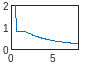

ylim([0,2])

% construction du meshgrid
Vr_temp = linspace(Vrmin,Vrmax,Npas);
Tr_temp = linspace(Trmin,Trmax,Npas);
Pr = zeros([Npas Npas])

Pr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

for i=1:Npas
    i
    Pr(i,:) = VDW_r_corrected_isothermes(Tr_temp(i),Vr_temp);
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

[Vr, Tr] = meshgrid(Vr_temp, Tr_temp);
% seuillage
Pr(Pr > 2) = 2;


% normalisation
Vr_norm = normalisation(Vrmin,Vrmax,Vr);
Tr_norm = normalisation(Trmin,Trmax,Tr);
Pr_norm = normalisation(min(min(Pr)), max(max(Pr)), Pr);

On passe à la triangulation :

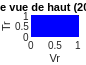

connect = delaunay(Vr_norm, Tr_norm);

triplot(connect,Vr_norm,Tr_norm);
xlabel('Vr')
ylabel('Tr')
title('Maillage vue de haut (20x20 points)')

Maintenant il faut fermer la figure :

- Extraction des bords

vmin = min(min(Vr_norm));
vmax = max(max(Vr_norm));
tmin = min(min(Tr_norm));
tmax = max(max(Tr_norm));

- Devant :

xq = linspace(vmin,vmax,Npas);
%yq = linspace(tmin,tmin,Npas);
zq = Pr_norm(1,1:Npas);%interp2(Vr_norm,Tr_norm,Pr_norm,xq,yq);

% triangulation
XQ = [xq xq];
ZQ = [zq linspace(0,0,Npas)];

sommets_dev = reshape([XQ ZQ], [], 2);
connect_dev = [];
for i=1:Npas-1
    connect_dev=[connect_dev [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_dev=transpose(reshape(connect_dev, 3, []));

% Ajout dans connect
connect_dev = connect_dev + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_dev;
sommet_dev_3d = reshape([XQ repmat(tmin,1,2*Npas) ZQ],[],3); % save this

- Derrière

xq = linspace(vmin,vmax,Npas);
%yq = linspace(tmax,tmax,Npas);
zq = Pr_norm(Npas,1:Npas);%interp2(Vr_norm,Tr_norm,Pr_norm,xq,yq);

% triangulation
XQ = [xq xq];
ZQ = [zq linspace(0,0,Npas)];

sommets_der = reshape([XQ ZQ], [], 2);
connect_der = [];
for i=1:Npas-1
    connect_der=[connect_der [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_der=transpose(reshape(connect_der, 3, []));

% Ajout dans connect
connect_der = connect_der + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_der;
sommet_der_3d = reshape([XQ repmat(tmax,1,2*Npas) ZQ],[],3); % save this

- Gauche

yq = linspace(tmin,tmax,Npas);
zq = Pr_norm(1:Npas,1).';%interp2(Vr_norm,Tr_norm,Pr_norm,xq,yq);

% triangulation
YQ = [yq yq];
ZQ = [zq linspace(0,0,Npas)];

sommets_g = reshape([YQ ZQ], [], 2);
connect_g = [];
for i=1:Npas-1
    connect_g=[connect_g [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_g=transpose(reshape(connect_g, 3, []));

% Ajout dans connect
connect_g = connect_g + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_g;
sommet_g_3d = reshape([repmat(vmin,1,2*Npas) YQ ZQ],[],3); % save this

- Droite

%xq = linspace(vmax,vmax,Npas);
yq = linspace(tmin,tmax,Npas);
zq = Pr_norm(1:Npas,Npas).';%interp2(Vr_norm,Tr_norm,Pr_norm,xq,yq);

% triangulation
YQ = [yq yq];
ZQ = [zq linspace(0,0,Npas)];

sommets_d = reshape([YQ ZQ], [], 2);
connect_d = [];
for i=1:Npas-1
    connect_d=[connect_d [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_d=transpose(reshape(connect_d, 3, []));

% Ajout dans connect
connect_d = connect_d + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_d;
sommet_d_3d = reshape([repmat(vmax,1,2*Npas) YQ ZQ],[],3); % save this

- En bas puis sauvegarde en stl

% union
sommet = reshape([reshape(Vr_norm,[],1) reshape(Tr_norm,[],1) reshape(Pr_norm, [], 1)], [], 3);
sommet(end+(1:2*Npas),:) = sommet_g_3d;
sommet(end+(1:2*Npas),:) = sommet_d_3d;
sommet(end+(1:2*Npas),:) = sommet_dev_3d;
sommet(end+(1:2*Npas),:) = sommet_der_3d;

%fermeture en bas
maxi = max(max(connect));
sommet(end+1,:)=[vmin tmin 0];
sommet(end+1,:)=[vmin tmax 0];
sommet(end+1,:)=[vmax tmax 0];
sommet(end+1,:)=[vmax tmin 0];
connect(end+1,:)=[maxi+1 maxi+2 maxi+4];
connect(end+1,:)=[maxi+2 maxi+3 maxi+4];

%sauvegarde en stl
tri = triangulation(connect, sommet);
stlwrite(tri, 'loi_vdw.stl')